clc; clear all; close all;
rng(0);

## Import data from file [generated from the Import tool]

trait_numbers = 20;
wave_numbers = 1721;

Table 1

data1 = readtable('data_part_1.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data1.Properties.VariableNames{1} = 'SampleID';

data_numbers1 = length(data1.SampleID);
trait_names = data1.Properties.VariableNames(2:21);
wave_lengths = str2double(data1.Properties.VariableNames(22:end));

spectra_data1 = table2array(data1(:,22:end));
traits_data1 = table2array(data1(:, 2:21));

Table 2

data2 = readtable('data_part_2.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data2.Properties.VariableNames{1} = 'SampleID';

data_numbers2 = length(data2.SampleID);
traitsIdx = [2 4 6 8 10 12 14 16 18 19 21 22 23 25 27 29 31 33 35 37];
spectra_data2 = table2array(data2(:,39:end));
traits_data2 = table2array(data2(:, traitsIdx));

Merged Table

spectra_data = [spectra_data1; spectra_data2];
traits_data = [traits_data1; traits_data2];

## Generate a table of statistics

meanVals = [];
minVals = [];
maxVals = [];
numMissing = [];
percentMissing = [];

for i = 1:numel(trait_names)
    meanVals = [meanVals; mean(traits_data(:, i), 'omitnan')];
    minVals = [minVals; min(traits_data(:, i))];
    maxVals = [maxVals; max(traits_data(:, i))];
    numMissing = [numMissing; sum(ismissing(traits_data(:, i)))];
    percentMissing = [percentMissing; 100*numMissing(end)/size(traits_data, 1)];
end

summaryTable = table(trait_names', meanVals, minVals, maxVals, numMissing, percentMissing,...
    'VariableNames', {'Variable', 'Mean', 'Min', 'Max', 'NumMissing', 'PercentMiss'});

disp(summaryTable);

                Variable                   Mean          Min           Max        NumMissing    PercentMiss
    ________________________________    __________    __________    __________    __________    ___________

    {'Anthocyanin content (μg/cm²)'}        1.2652       0.56104        2.9811      12597          94.75   
    {'Boron content (mg/cm²)'      }    0.00041765      7.76e-06     0.0023379       9266         69.695   
    {'C content (mg/cm²)'          }        6.6214       0.10275        37.292       7406         55.705   
    {'Ca content (mg/cm²)'         }        0.1156    0.00069226       0.98872       9375         70.515   
    {'Carotenoid content (μg/cm²)' }        9.1649        1.1826        40.443       8653         65.085   
    {'Cellulose (mg/cm²)'          }   

## Loop over traits

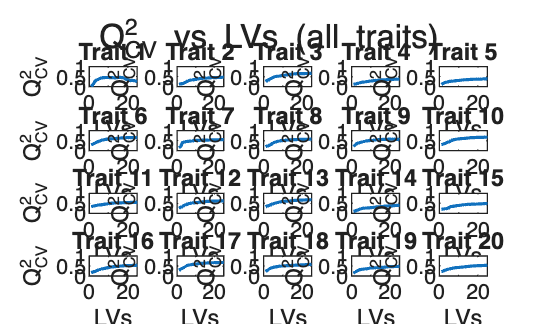

% Define figures for grouped subplots
figure_Q2      = figure('Name','Q^2 across traits');
figure_RMSE    = figure('Name','RMSE across traits');
figure_Betas   = figure('Name','PLS Coefficients');
figure_R2      = figure('Name','Explained Variance');
figure_Scatter = figure('Name','PLS Estimation');
figure_Resid   = figure('Name','PLS Residuals');
figure_SPE     = figure('Name','SPE Control Charts');
figure_T2      = figure('Name','T2 Control Charts');

for traitIdx = 1:20
    %% Trait to predict
    Ytrait = traits_data(:, traitIdx);
    traitMiss = isnan(Ytrait);
    Ytrait = Ytrait(~traitMiss, :);
    Xtrait = spectra_data(~traitMiss, :);

    %% Data division
    model(traitIdx).X0 = Xtrait;
    model(traitIdx).Y0 = Ytrait;
    
    % number of observation
    nobs    = length(model(traitIdx).Y0);
    % cross validation
    part    = cvpartition(nobs, 'HoldOut', 0.3);
    % train
    idxCal  = training(part);
    % test
    idxTest = test(part);
    
    % z-score scandalize
    [model(traitIdx).XCal, model(traitIdx).mu, model(traitIdx).sigma] = zscore(model(traitIdx).X0(idxCal, :));
    model(traitIdx).XTest = normalize(model(traitIdx).X0(idxTest,:), 'center', model(traitIdx).mu, 'scale', model(traitIdx).sigma);
    
    % mean centering
    model(traitIdx).YCal = model(traitIdx).Y0(idxCal) - mean(model(traitIdx).Y0(idxCal));
    model(traitIdx).YTest = model(traitIdx).Y0(idxTest) - mean(model(traitIdx).Y0(idxCal));

    %% Cross-validation
    X = model(traitIdx).X0(idxCal, :);
    Y = model(traitIdx).Y0(idxCal);
    k = 5;
    cv = cvpartition(size(Y, 1), 'KFold', k);

    PRESSPLS = zeros(k,25);
    Q2PLS    = zeros(k,25);
    RMSEPLS  = zeros(k,25);

    for i = 1:cv.NumTestSets
        % cross validation
        trainIdx = training(cv, i);
        testIdx  = test(cv, i);

        X_cal  = X(trainIdx, :);
        Y_cal  = Y(trainIdx, :);
        X_val  = X(testIdx, :);
        Y_val  = Y(testIdx, :);
        
        % z-score
        [XCal, mu, sigma] = zscore(X_cal);
        XVal = normalize(X_val, "center", mu, "scale", sigma);
        
        % mean centering
        YCal = Y_cal - mean(Y_cal);
        YVal = Y_val - mean(Y_cal);
        
        %%% ybar_cal = mean(yc);
        %%% tss_f   = sum((yv - ybar_cal).^2);
        %%% Q2_folds(f,a)    = 1 - press_f / max(tss_f, eps); 
        TSS = sum((YVal - mean(YCal)).^2);
        [rows, ~] = size(XVal);

        for j = 1:25
            [~, ~, ~, ~, bPLS] = plsregress(XCal, YCal, j);
            YPredPLS = [ones(rows,1) XVal] * bPLS;
            PRESSPLS(i,j) = sum((YVal - YPredPLS).^2);
            Q2PLS(i,j) = 1 - PRESSPLS(i,j)/TSS;
            RMSEPLS(i,j) = sqrt(mean((YPredPLS - YVal).^2));
        end
    end

    Q2_CV_PLS = mean(Q2PLS);
    RMSE_CV_PLS = mean(RMSEPLS);

    %% Optimal number of LVs
    threshold = 0.99 * max(Q2_CV_PLS);
    noPCsPLS = find(Q2_CV_PLS >= threshold, 1, 'first');
    if isempty(noPCsPLS)
        noPCsPLS = 3;
    end
    
    % save optimal number of LVs
    model(traitIdx).nLV = noPCsPLS;   

    %% Final PLS fit
    %%% mean centering before
    % [model(traitIdx).YCal, muY, sigmaY] = zscore(model(traitIdx).YCal);
    % model(traitIdx).YTest = normalize(model(traitIdx).YTest, 'center', muY, 'scale', sigmaY);
    [P, Q, T, U, bPLS, varPLS, mse, stats] = plsregress(model(traitIdx).XCal, model(traitIdx).YCal, noPCsPLS);

    %% Predictions
    [row, ~] = size(model(traitIdx).XTest);
    YTestPred = [ones(row, 1) model(traitIdx).XTest] * bPLS;
    resid = abs(model(traitIdx).YTest - YTestPred);

    PRESS_test = sum((YTestPred - model(traitIdx).YTest).^2);
    %%% use train %%%
    TSS_test = sum((model(traitIdx).YTest - mean(model(traitIdx).YCal)).^2);
    Q2_test = 1 - PRESS_test / TSS_test;
    RMSE_test = sqrt(mean((model(traitIdx).YTest - YTestPred).^2));

    Q2_test_all(traitIdx) = Q2_test;
    RMSE_test_all(traitIdx) = RMSE_test;


    %% ---- SPE & T² ----
    % SPE (Squared Prediction Error)
    X_hat = T * P';              % Reconstructed X
    E = model(traitIdx).XCal - X_hat;
    SPE = sum(E.^2, 2);

    % Hotelling's T²
    covT = cov(T);
    T2 = sum((T / covT) .* T, 2);

    % Control limits (99.73% confidence)
    alpha = 0.0027;
    SPE_limit = mean(SPE) + std(SPE)*norminv(1-alpha);
    T2_limit = chi2inv(1-alpha, noPCsPLS);

    %% Plot 1: Q² vs LVs
    figure(figure_Q2);
    subplot(4,5,traitIdx);
    plot(Q2_CV_PLS, 'LineWidth', 1.2);
    title(sprintf('Trait %d', traitIdx));
    xlabel('LVs'); ylabel('Q^2_{CV}'); ylim([0 1]);

    %% Plot 2: RMSE vs LVs
    figure(figure_RMSE);
    subplot(4,5,traitIdx);
    plot(RMSE_CV_PLS, 'LineWidth', 1.2);
    title(sprintf('Trait %d', traitIdx));
    xlabel('LVs'); ylabel('RMSE_{CV}');

    %% Plot 3: Coefficients
    figure(figure_Betas);
    subplot(4,5,traitIdx);
    betas = bPLS(2:end);
    bar(betas);
    title(sprintf('Trait %d', traitIdx));
    xlabel('Wavelength index'); ylabel('β');

    %% Plot 4: Explained variance
    figure(figure_R2);
    subplot(4,5,traitIdx);
    R2_X_PLS = cumsum(varPLS(1,:));
    R2_Y_PLS = cumsum(varPLS(2,:));
    plot(R2_X_PLS*100, 'LineWidth', 1.2); hold on;
    plot(R2_Y_PLS*100, 'LineWidth', 1.2);
    title(sprintf('Trait %d', traitIdx));
    xlabel('LVs'); ylabel('R^2 [%]');
    legend({'X','Y'}, 'Location', 'best'); hold off;

    %% Plot 5: Scatter YTest vs YPred
    figure(figure_Scatter);
    subplot(4,5,traitIdx);
    scatter(model(traitIdx).YTest, YTestPred, 'filled');
    xlabel('True'); ylabel('Predicted');
    title(sprintf('Trait %d', traitIdx));
    axis equal;
    text(min(model(traitIdx).YTest), max(YTestPred), sprintf('Q^2=%.2f', Q2_test), 'FontSize',8);

    %% Plot 6: Residuals
    figure(figure_Resid);
    subplot(4,5,traitIdx);
    scatter(model(traitIdx).YTest, resid, 'filled');
    xlabel('True'); ylabel('|Error|');
    title(sprintf('Trait %d', traitIdx));

    %% Plot 7: SPE Control Chart
    figure(figure_SPE);
    subplot(4,5,traitIdx);
    plot(SPE, 'bo-','MarkerSize',3); hold on;
    yline(SPE_limit,'r--','Limit');
    title(sprintf('Trait %d', traitIdx));
    xlabel('Sample'); ylabel('SPE'); hold off;

    %% Plot 8: T² Control Chart
    figure(figure_T2);
    subplot(4,5,traitIdx);
    plot(T2, 'ko-','MarkerSize',3); hold on;
    yline(T2_limit,'r--','Limit');
    title(sprintf('Trait %d', traitIdx));
    xlabel('Sample'); ylabel('T^2'); hold off;
end

% Super titles
sgtitle(figure_Q2, 'Q^2_{CV} vs LVs (all traits)');

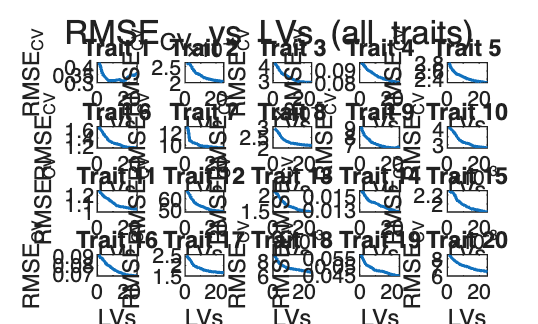

sgtitle(figure_RMSE, 'RMSE_{CV} vs LVs (all traits)');

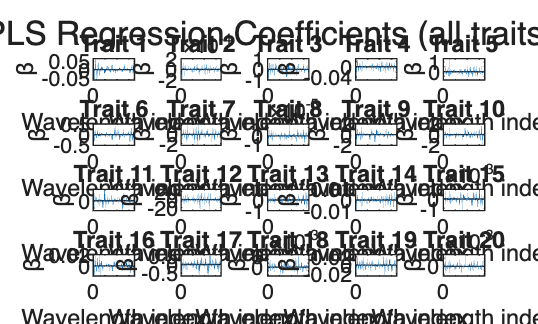

sgtitle(figure_Betas, 'PLS Regression Coefficients (all traits)');

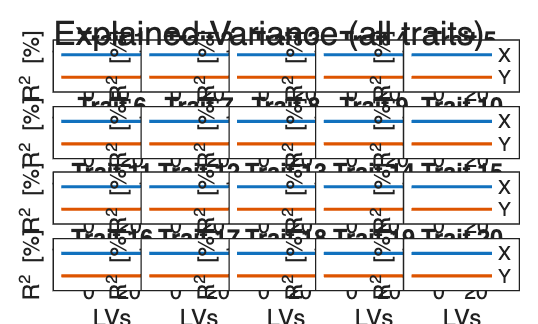

sgtitle(figure_R2, 'Explained Variance (all traits)');

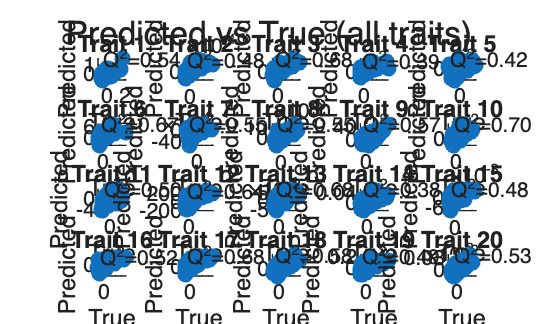

sgtitle(figure_Scatter, 'Predicted vs True (all traits)');

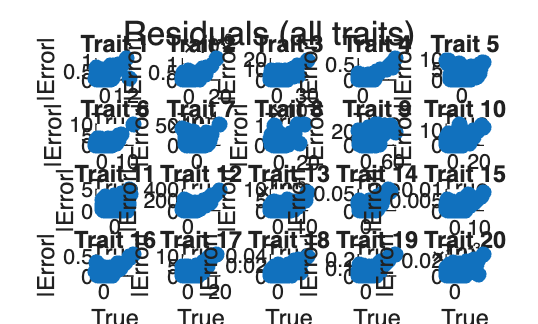

sgtitle(figure_Resid, 'Residuals (all traits)');

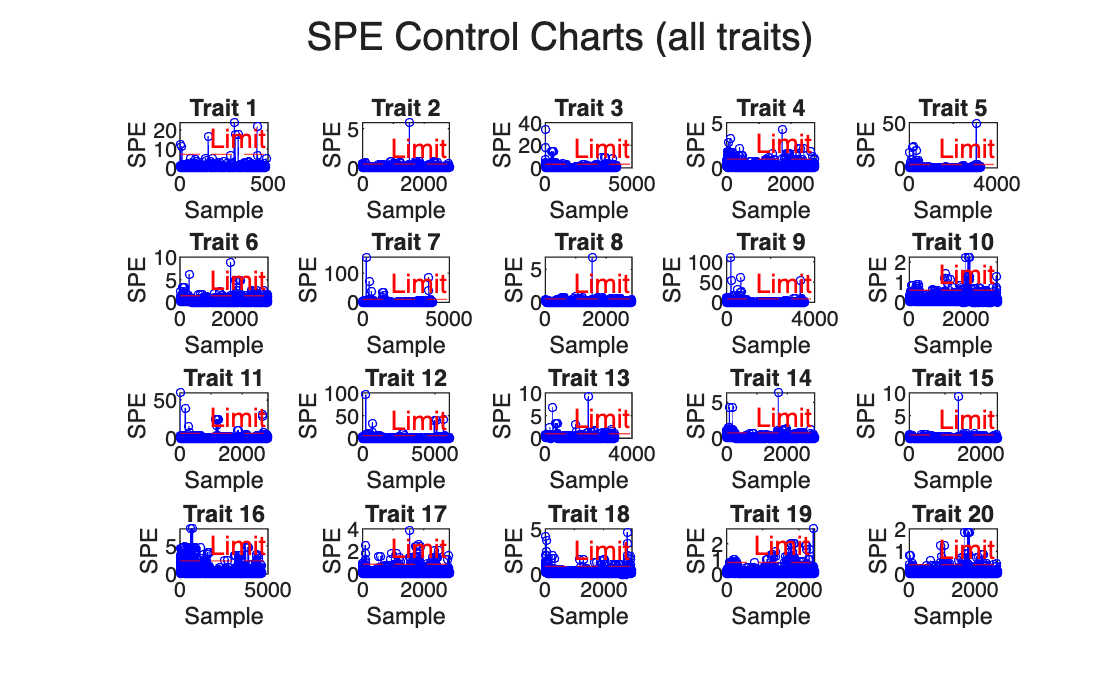

sgtitle(figure_SPE, 'SPE Control Charts (all traits)');

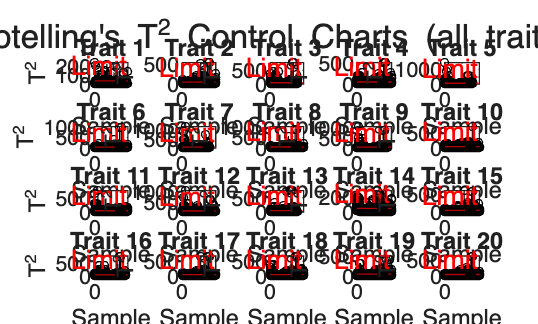

sgtitle(figure_T2, 'Hotelling''s T^2 Control Charts (all traits)');

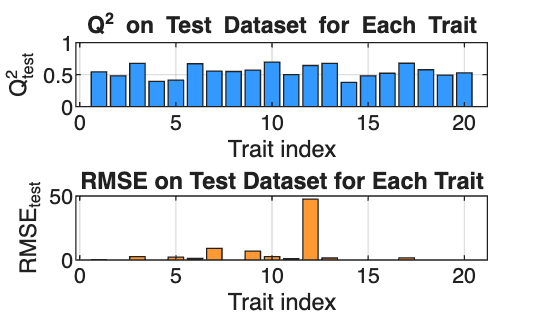


%% Plot overall Q² and RMSE for test sets
figure('Name', 'Test Set Performance');

subplot(2,1,1);
bar(Q2_test_all, 'FaceColor', [0.2 0.6 1]);
xlabel('Trait index');
ylabel('Q^2_{test}');
title('Q^2 on Test Dataset for Each Trait');
ylim([0 1]);
grid on;

subplot(2,1,2);
bar(RMSE_test_all, 'FaceColor', [1 0.6 0.2]);
xlabel('Trait index');
ylabel('RMSE_{test}');
title('RMSE on Test Dataset for Each Trait');
grid on;

%% ====================== A2 MISSING PARTS – RUN AFTER YOUR LOOP ======================
% model(1:20).XCal, YCal, XTest, YTest, nLV，
% Q2_test_all, RMSE_test_all。

%—— 1) chose worst 5 traits by Q^2_test ——%
[~, worstIdx] = mink(Q2_test_all, 5);
fprintf('Worst 5 traits by Q^2_test: %s\n', mat2str(worstIdx));

Worst 5 traits by Q^2_test: [14 4 5 2 15]


Trait 14: nCal=2897, outliers=303


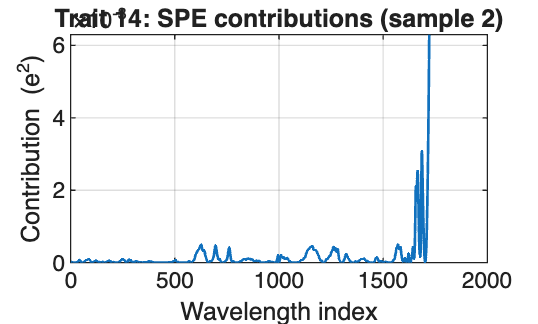

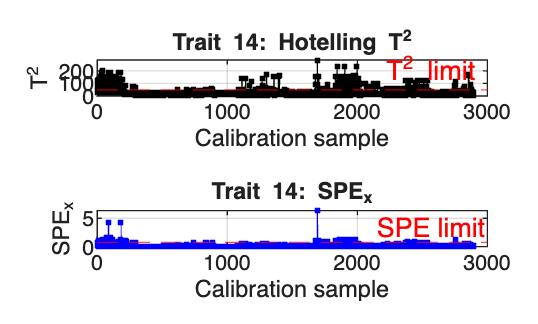

Trait 4: nCal=2744, outliers=218


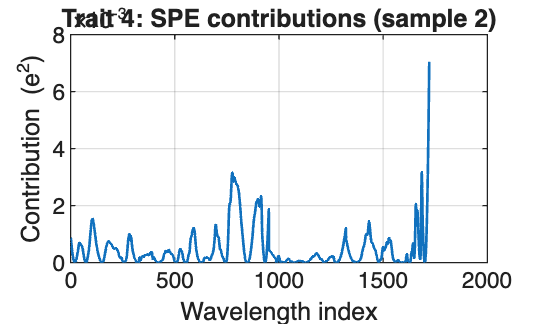

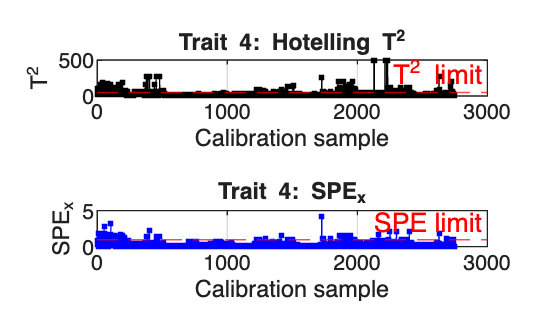

Trait 5: nCal=3250, outliers=257


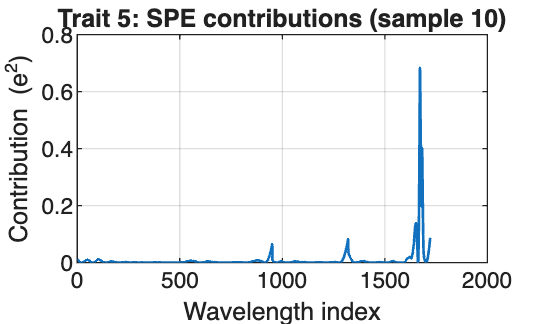

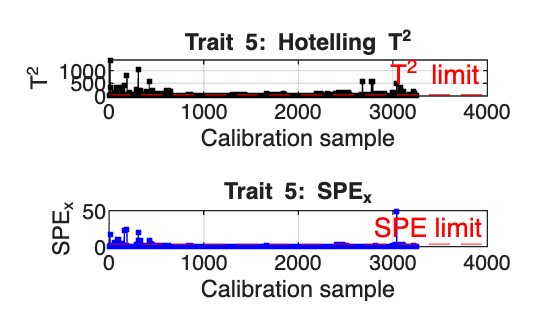

Trait 2: nCal=2821, outliers=201


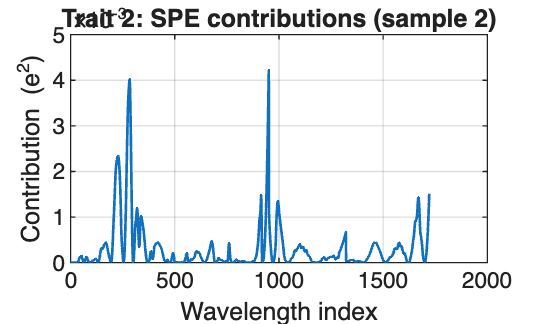

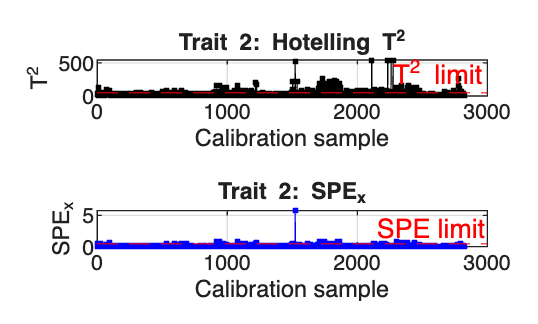

Trait 15: nCal=2467, outliers=135


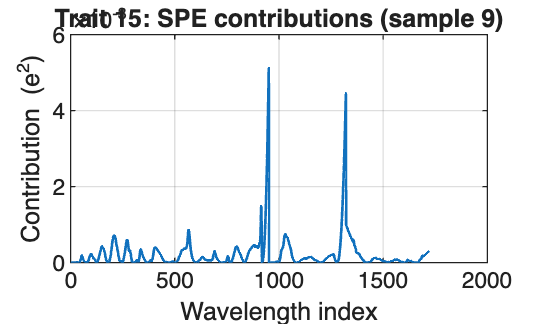

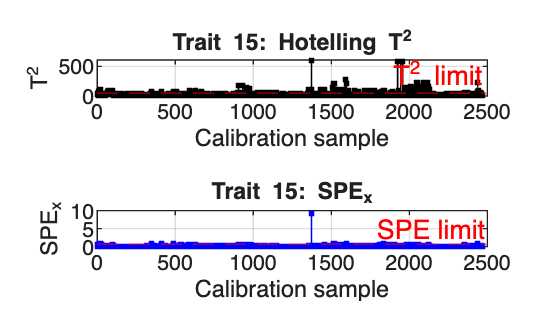


% result summary
Improvement = table('Size',[0 7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'Trait','nCal','nOutliers','Q2_old','Q2_new','RMSE_old','RMSE_new'});

alpha = 0.0027;   
show_contrib_plot = true; 

for t = worstIdx(:)'
    % get data
    Xcal  = model(t).XCal;
    Ycal  = model(t).YCal;
    Xtest = model(t).XTest;
    Ytest = model(t).YTest;
    A     = model(t).nLV;
    
    % current numbers of cal
    ncal = size(Xcal,1);
    %—— 2) PLS ——%
    [P, ~, T, ~, bPLS] = plsregress(Xcal, Ycal, A);

    %—— 3) compute SPE_x and T², control limit ——%
    % X reconstruction
    Xhat = T * P';
    E    = Xcal - Xhat;

    % 3a) T2 control limit
    ST = cov(T); 
    STi = pinv(ST);
    T2  = sum((T * STi) .* T, 2);
    % T2_limit = (A*(ncal-1)/(ncal-A)) * finv(1-alpha, A, ncal-A);
    T2_limit = chi2inv(1-alpha, noPCsPLS);

    % 3b) SPE_x control limit
    % Ce = cov(E);
    % Ce = (Ce + Ce')/2;
    % [V,D] = eig(Ce);
    % lambda = max(real(diag(D)), 0);  
    % phi1 = sum(lambda);
    % phi2 = sum(lambda.^2);
    % phi3 = sum(lambda.^3);
    % h0 = 1 - (2*phi1*phi3)/(3*phi2^2);
    % h0 = max(min(h0,1-1e-6), 1e-6); 
    % ca = norminv(1-alpha);
    % SPE = sum(E.^2, 2);
    % SPE_limit = phi1 * ( (ca*sqrt(2*phi2*h0^2)/phi1) + 1 + (phi2*h0*(h0-1))/phi1^2 )^(1/h0);
    
    SPE = sum(E.^2, 2);
    SPE_limit = mean(SPE) + std(SPE)*norminv(1-alpha);

    %—— 4) find control limit index ——%
    exceedIdx = find(SPE > SPE_limit | T2 > T2_limit);
    fprintf('Trait %d: nCal=%d, outliers=%d\n', t, ncal, numel(exceedIdx));

    if show_contrib_plot && ~isempty(exceedIdx)
        % use first as example
        s = exceedIdx(1);  
        % wavelength contribution
        contribSPE = E(s,:).^2;  
        figure('Name',sprintf('Trait %d - SPE wavelength contributions (sample %d)', t, s));
        plot(contribSPE, 'LineWidth', 1.0);
        xlabel('Wavelength index'); ylabel('Contribution (e^2)');
        title(sprintf('Trait %d: SPE contributions (sample %d)', t, s));
        grid on;
    end

    %—— 5) baseline ——%
    Q2_old   = Q2_test_all(t);
    RMSE_old = RMSE_test_all(t);

    %—— 6) exceeding samples are excluded ——%
    keep = true(ncal,1);
    keep(exceedIdx) = false;

    if any(keep) && sum(keep) > A
        % not renormalization
        [~, ~, ~, ~, bPLS_new] = plsregress(Xcal(keep,:), Ycal(keep), A);

        % pred
        Ypred_new  = [ones(size(Xtest,1),1) Xtest] * bPLS_new;

        PRESS_new  = sum((Ytest - Ypred_new).^2);
        TSS_new    = sum((Ytest - mean(Ycal)).^2);  % mean(Ycal)=0 时即 sum(Ytest.^2)
        Q2_new     = 1 - PRESS_new / TSS_new;
        RMSE_new   = sqrt(mean((Ytest - Ypred_new).^2));
    else
        % If too few samples remain after removal,
        % do not retrain (keep the original model values).
        Q2_new   = Q2_old;
        RMSE_new = RMSE_old;
        warning('Trait %d: The remaining samples are insufficient for retraining; keep the original model metrics.', t);
    end

    %—— 7) save log ——%
    Improvement = [Improvement; {t, ncal, numel(exceedIdx), Q2_old, Q2_new, RMSE_old, RMSE_new}]; %#ok<AGROW>

    %—— 8) control chart ——%
    figure('Name',sprintf('Trait %d - Control Charts', t));
    tiledlayout(2,1);
    nexttile;
    plot(T2,'k.-'); hold on; yline(T2_limit,'r--','T^2 limit'); hold off;
    xlabel('Calibration sample'); ylabel('T^2'); title(sprintf('Trait %d: Hotelling T^2', t)); grid on;
    nexttile;
    plot(SPE,'b.-'); hold on; yline(SPE_limit,'r--','SPE limit'); hold off;
    xlabel('Calibration sample'); ylabel('SPE_x'); title(sprintf('Trait %d: SPE_x', t)); grid on;
end


%—— 9) print improvement ——%
disp('=== A2 Outlier-Removal Refit: Test Performance Comparison ===');

=== A2 Outlier-Removal Refit: Test Performance Comparison ===


Improvement

Improvement = 5×7 table
    Trait    nCal    nOutliers    Q2_old     Q2_new      RMSE_old      RMSE_new 
    _____    ____    _________    _______    _______    __________    __________

     14      2897       303       0.38016    0.18712      0.012071      0.013823
      4      2744       218       0.39406     0.2392      0.081348      0.091153
      5      3250       257       0.41556    0.20258        2.1915        2.5599
      2      2821       201       0.47994    0.38795    0.00016903    0.00018337
     15      2467       135       0.48163    0.43346     0.0017304      0.001809


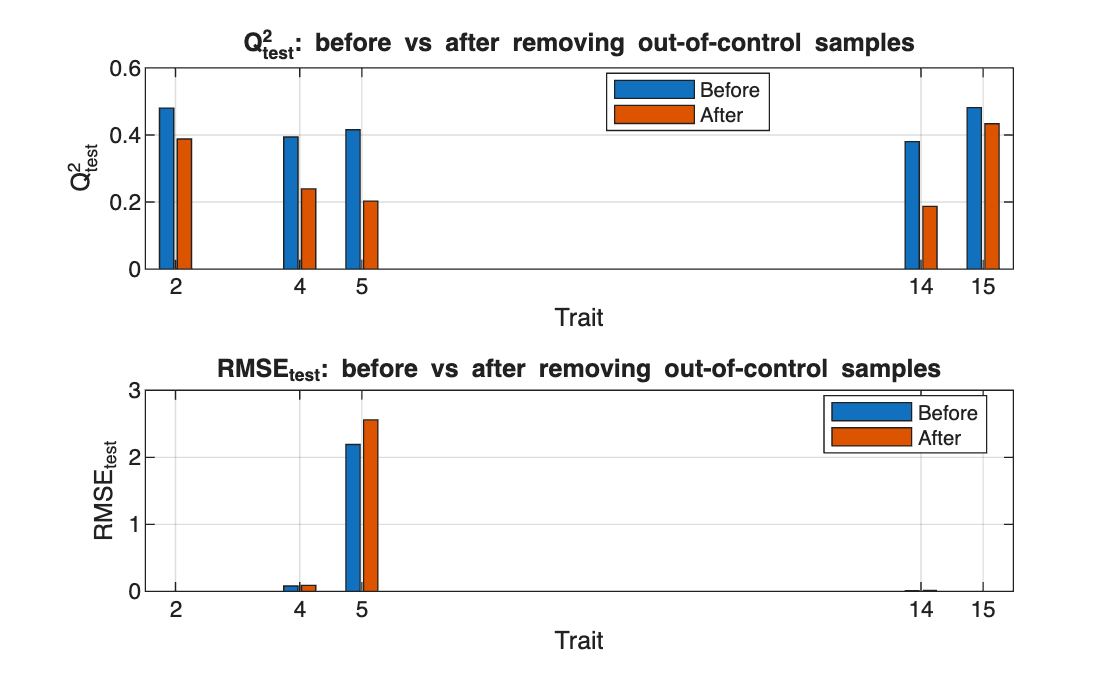


figure('Name','A2 Outlier Removal – Q^2/ RMSE Improvement');
tiledlayout(2,1);

nexttile;
bar(Improvement.Trait, [Improvement.Q2_old, Improvement.Q2_new], 'grouped');
xlabel('Trait'); ylabel('Q^2_{test}');
title('Q^2_{test}: before vs after removing out-of-control samples');
legend({'Before','After'},'Location','best'); grid on;

nexttile;
bar(Improvement.Trait, [Improvement.RMSE_old, Improvement.RMSE_new], 'grouped');
xlabel('Trait'); ylabel('RMSE_{test}');
title('RMSE_{test}: before vs after removing out-of-control samples');
legend({'Before','After'},'Location','best'); grid on;